# **drawSpline**

Draw 2-D cubic spline curve fits  given points.

## Description

## Syntax

drawSpline(ctype,xp,yp)

drawSpline(ctype,xp,yp,'-s1',u,'-s2',v)

drawSpline(__,LineSpec)

p = drawSpline(__)

### Description

drawSpline(ctype,xp,yp) draw cubic spline with default number of points. 

drawSpline(ctype,xp,yp,LineSpec)  sets the line style, marker symbol, and color.

drawSpline(ctypexp,yp,'-np',np) draw curve using np points.

p = drawSpline(__) returns structure with fields contain x-value and y-value for the curve.

### Method

For calculation of the coordinates of the curve **drawSpline **call function **evalSpline( xp, yp,np)  **which returns coordinates *x *and *y *of the curve at given values of parameter *t*.  Function **evalSpline **use MATLAB function **spline**.  

The function **evalSpline** calculates the parameter range based upon chord distance between 

data points rather than using normalized splines. 

The curve is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**ctype -** Spline type: 

- 1= cubic:  

- 2=Wilson-Fowler: the chord length as the independent parameter

**xp - **x-coordinate of polygon vertices (real vector)

**yp **- y-coordinate of polygon vertices (real vector)

xp, yp must be of the same size.

### Optional Name-Value Pair Input Arguments

**'-s1',u1**  - slope vector at start point  (if u2 is not given than u2=[0 0])

**'-s2',u2** - slope vector at end point (if u1 is not given than u1=[0 0])

**'-np',** **np **- number of points along the curve, np is scalar integer value > 2.

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with fields

- p.xk, p.yk - spline end points 

- p.th - tangen angle in end points in degrees

- p.x  - spline coordinates

- p.y

- p.color - line color

## Examples

### Example 1

drawInit
% coordinates of polygon vertices
xp=[1 2 4 3];
yp=[1 3 3 1];
% plot definiting polygon vertices
scatter(xp,yp,'r')
% plot definiting polygon
plot(xp,yp,'r')
% draw curve
p = drawSpline(1,xp,yp)

p = struct with fields:
       th: [105.5241 -141.9530]
        x: [1×100 double]
        y: [1×100 double]
       xk: [1 3]
       yk: [1 1]
    color: 'k'


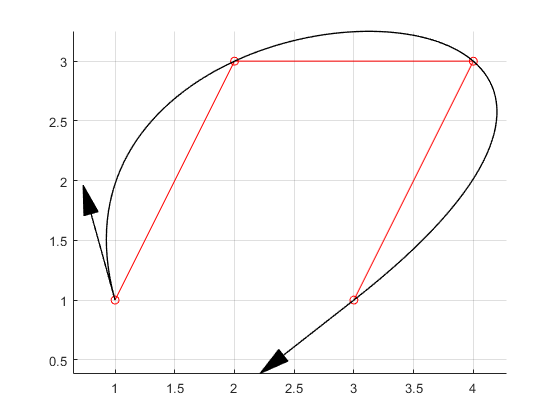

drawArrow(3,0.25,0.125,xp(1),yp(1),'-rtheta',1,p.th(1))
drawArrow(3,0.25,0.125,xp(4),yp(4),'-rtheta',1,p.th(2))
grid on

### Example2

figure
hold on
axis equal
% coordinates of polygon vertices
xp=[1 2 4 3];
yp=[1 3 3 1];
u = [2-1, 3-1];
v = [3-4,1-3];
% plot definiting polygon vertices
scatter(xp,yp,'r')
% plot definiting polygon
plot(xp,yp,'r')
% draw curve
p = drawSpline(1,xp,yp,'-s1',u,'-s2',v);
p = drawSpline(1,xp,yp,'-s1',u,'k')

p = struct with fields:
       th: [63.4349 82.8750]
        x: [1×100 double]
        y: [1×100 double]
       xk: [1 3]
       yk: [1 1]
    color: [0 0 0]


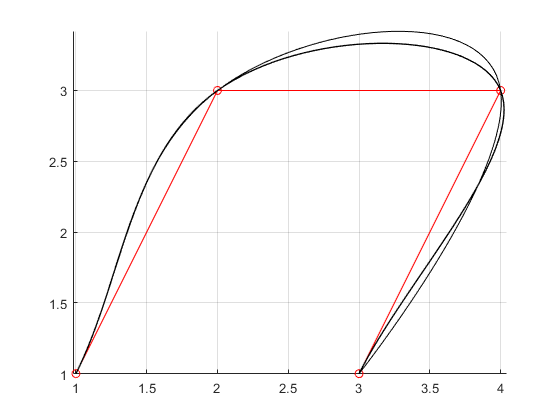

grid on

#### **Example 3**

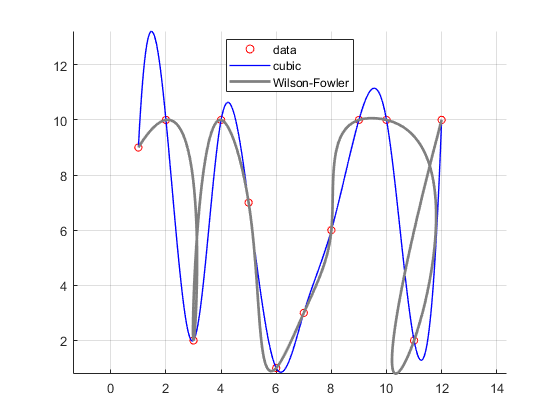

drawInit
% coordinates of polygon vertices
nv = 12; % number of vertices
xv=1:nv; %randi(10,nv,1);
yv=randi(10,nv,1);
% plot vertices
scatter(xv,yv,30,'r')
% plot definiting polygon
%plot(xv,yv,'r:')
% plot calculated points
% draw curve using 50 points in gray color
b1 = drawSpline(1,xv,yv,'-np',250,'LineWidth',1,'Color','b');
b = drawSpline(2,xv,yv,'-np',250,'LineWidth',2,'Color',[1 1 1]*0.5);
% label every 10th point
%scatter(b.x(1:10:end),b.y(1:10:end),30,'k','filled')
legend({'data','cubic','Wilson-Fowler'},'Location','best')
grid on

#### **Example 4**

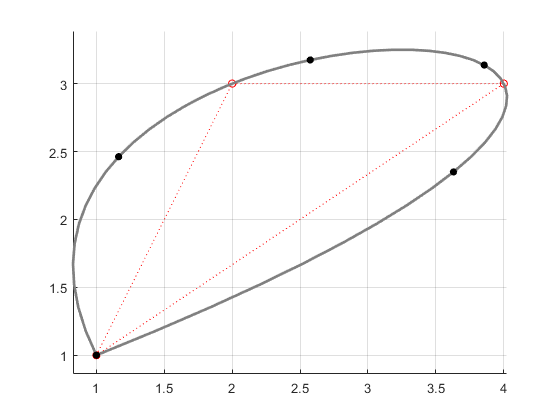

figure
axis equal
hold on
% coordinates of polygon vertices
xv = [ 1 2 4 1];
yv = [ 1 3 3 1];
% plot vertices
scatter(xv,yv,30,'r')
% plot definiting polygon
plot(xv,yv,'r:')
% plot calculated points
% draw curve using 50 points in gray color
b = drawSpline(1,xv,yv,'-np',50,'LineWidth',2,'Color',[1 1 1]*0.5);
% label every 10th point
scatter(b.x(1:10:end),b.y(1:10:end),30,'k','filled')
grid on

## See also

[Spline](https://en.wikipedia.org/wiki/Spline_(mathematics))

## References